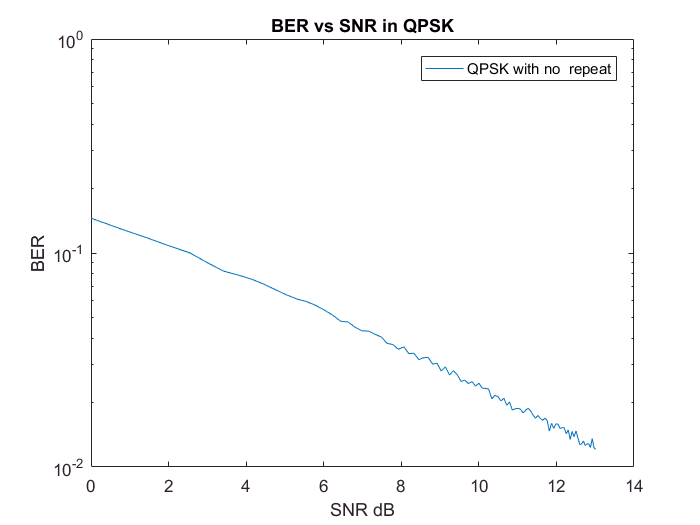


 clc
 clear all;

%generate the data bits 
N = 50000;
repeat = 0 ; %repeation flag 
col = 1;  %determine number of bits per symbol

% generate random  bits and map them to -1  and 1
%assuming tb and Eo = 1 

data_bits = randi([0 1 ] , N,col);
data = [];


if(repeat > 0) 
    N= N*3;
    data_bits_  = repelem(data_bits,3,1);

    step = 3; %will be used in descion making
else
    data_bits_ = data_bits;
    step =1;
end

temp = reshape(data_bits_,2,N/2)';

for k = 1:N/2
    if(temp(k,:) == [0 0])
        data =[data -1-j];
    elseif (temp(k,:) == [0 1])
        data = [data -1+j];
    elseif (temp(k,:) == [1 0])
        data =[data  1-j];
    elseif (temp(k,:) == [1 1])
        data = [data 1+j];
    end
       end
data = transpose(data);


%  c = reshape(data_bits+48,2,N/2)';
% symbol =bin2dec(char(c))';
% A=[ 1 -1] 
% 
% data = A(floor(data_bits/2)+1) + 1i* A(mod(data_bits,2)+1)

%channel creation
h =  (normrnd(0,sqrt(0.5),N/2,1)+j*normrnd(0,sqrt(0.5),N/2,1));

%generation of noise and getting the result  output at
%different No

BERq= [];
recieved_bits = zeros(N/2,2);
for S = 1:0.2:20   %signal to noise ratio steps 
    No = 1/S ; 
    %noise generation n 
    n = normrnd(0,sqrt(No/2),N/2,1)-j*normrnd(0,sqrt(No/2),N/2,1);
    %output formula  
    y = data.*h + n ;
    %there is no need for a correlator since
    %we work with base band signals 
    
    recieved_sig = y./h; %compensate for channel gain
    
    % descion making
 for i = 1:step:length(recieved_sig)
 %****** with repeat*******%       
        if (repeat >0)
            
    if (real(recieved_sig(i)) >0  &&  real(recieved_sig(i+1)) >0 )||(real(recieved_sig(i)) >0  &&  real(recieved_sig(i+2)) >0 )||(real(recieved_sig(i+1)) >0  &&  real(recieved_sig(i+2)) >0 )
            recieved_bits(i,1) = 1;
            recieved_bits(i+1,1) = 1;
            recieved_bits(i+2,1) = 1;
            else
              recieved_bits(i,1) = 0;
            recieved_bits(i+1,1) = 0;
            recieved_bits(i+2,1) = 0;
    end
            
%for quadrature part
    if (imag(recieved_sig(i)) >0  &&  imag(recieved_sig(i+1)) >0 )||(imag(recieved_sig(i)) >0  &&  imag(recieved_sig(i+2)) >0 )||(imag(recieved_sig(i+1)) >0  &&  imag(recieved_sig(i+2)) >0 )

            recieved_bits(i,2) = 1;
            recieved_bits(i+1,2) = 1;
            recieved_bits(i+2,2) = 1;
            else
            recieved_bits(i,2) = 0;
            recieved_bits(i+1,2) = 0;
            recieved_bits(i+2,2) = 0;
            end
                
          %***** no repeat descion****%            
  
        else
       if (real(recieved_sig(i)) < 0 ) && (imag(recieved_sig(i)) < 0 )
           recieved_bits(i,:) = [0 ; 0 ];
       elseif    (real(recieved_sig(i)) < 0 ) && (imag(recieved_sig(i)) > 0 )
           recieved_bits(i,:) = [0 ; 1];
           
       elseif    (real(recieved_sig(i)) > 0 ) && (imag(recieved_sig(i)) > 0 )
           recieved_bits(i,:) = [1; 1];
        elseif    (real(recieved_sig(i)) > 0 ) && (imag(recieved_sig(i)) < 0 )
           recieved_bits(i,:) = [1 ; 0];
       end
        

    end
end
%check the BER using built in function symerr
recieved_bits_ = reshape(recieved_bits',N,1);
[different,ratio] = symerr(recieved_bits_,data_bits_);
BERq = [BERq ratio];
end
SNR = 1:0.2:20;
SNR_db = 10*log10(SNR);

semilogy(SNR_db,BERq);
title('BER vs SNR in QPSK');
legend('QPSK with no  repeat');

xlabel('SNR dB');
ylabel('BER');